# Image Enhancement in the Spatial Domain 3

using local/global information

Created time : 2024/3/22 09:14

學號 : 109321019    姓名 : 涂价弘

## Exercise-1

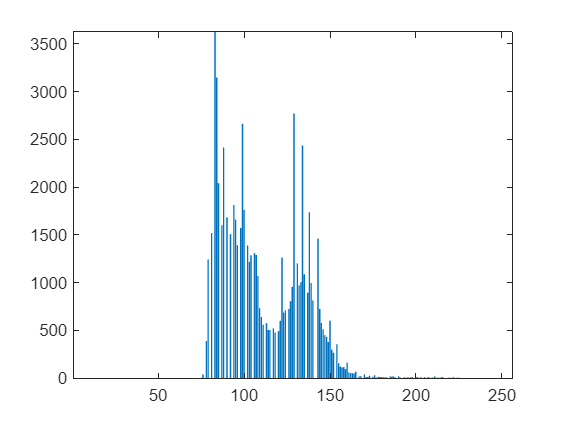

clf('reset');
img = imread('./images/2/pout.tif');
hist = gen_hist(img);
bar(hist)
axis tight

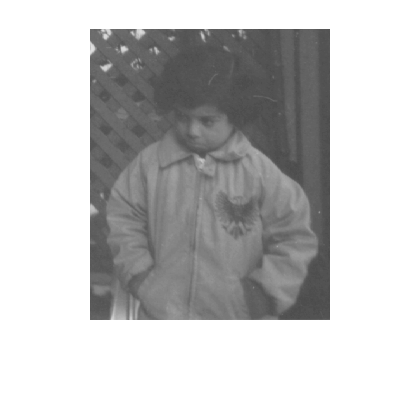

imshow(img)

## Exercise-2

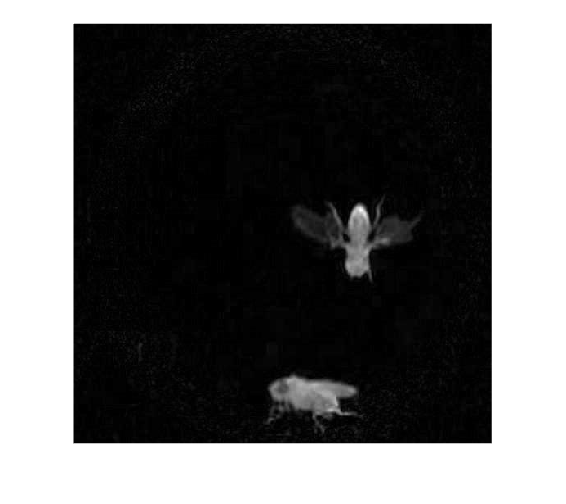

clf('reset');

img = imread('./images/flyman/flymanBS.tif');
imshow(img)

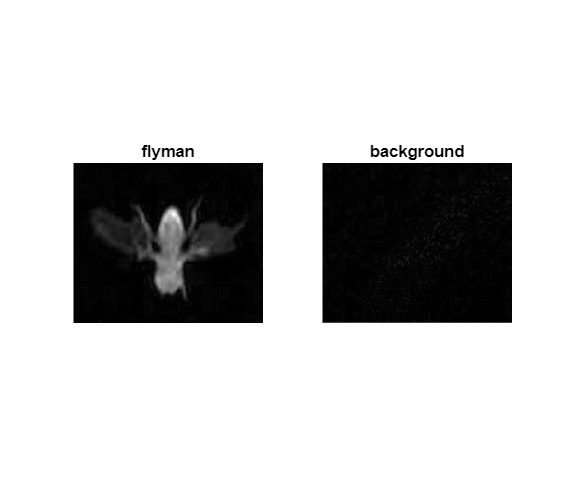


flyman = img(176:339, 250:444);
flyman_hist = gen_hist(flyman);

bg = img(1:163, 1:194);
bg_hist = gen_hist(bg);

subplot(1, 2, 1)
imshow(flyman)
title('flyman')
subplot(1, 2, 2)
imshow(bg)
title('background')

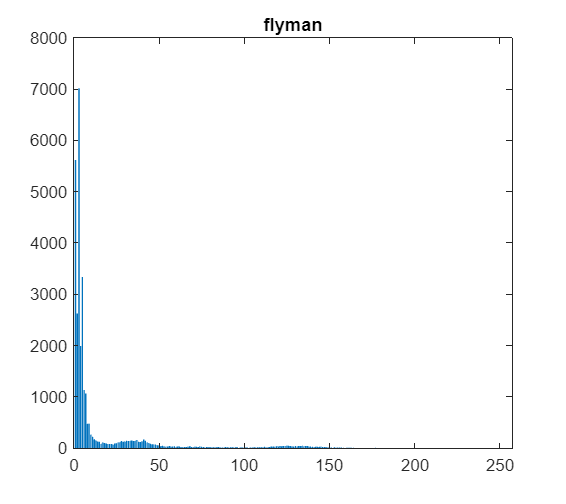


clf('reset');

bar(flyman_hist)
title('flyman')

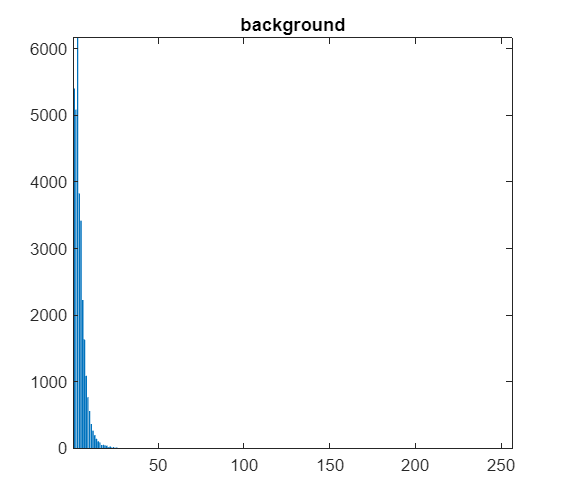


bar(bg_hist)
axis tight
title('test')
title('background')

## Exercise-3

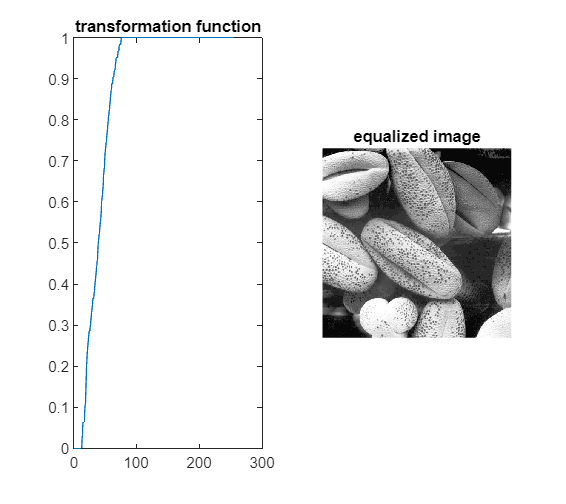

clf('reset')

img1 = imread('./images/3/Fig3.15(a)1top.jpg');
img2 = imread('./images/3/Fig3.15(a)2.jpg');
img3 = imread('./images/3/Fig3.15(a)3.jpg');

[equaized_img1, t1] = histeq(img1);
[equaized_img2, t2] = histeq(img2);
[equaized_img3, t3] = histeq(img3);

subplot(1, 2, 1)
plot(t1)
title('transformation function')
subplot(1, 2, 2)
imshow(equaized_img1)
title('equalized image')

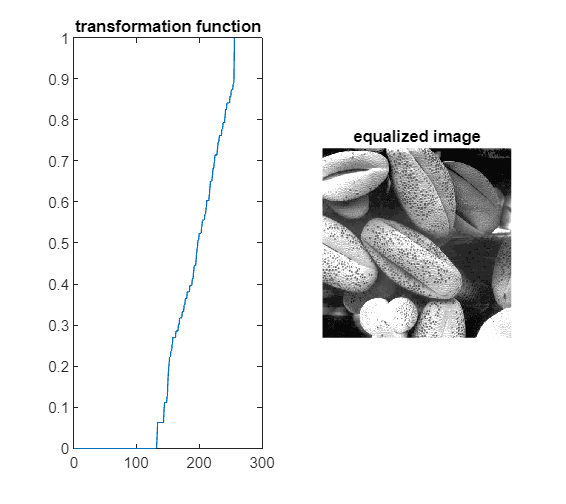


clf('reset')

subplot(1, 2, 1)
plot(t2)
title('transformation function')
subplot(1, 2, 2)
imshow(equaized_img2)
title('equalized image')

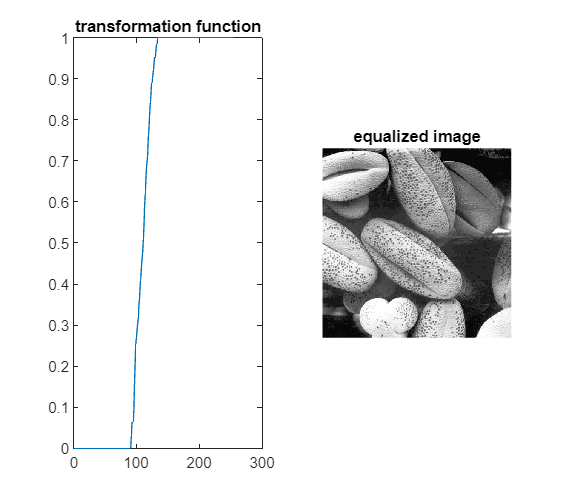


clf('reset')

subplot(1, 2, 1)
plot(t3)
title('transformation function')
subplot(1, 2, 2)
imshow(equaized_img3)
title('equalized image')

## Exercise-4

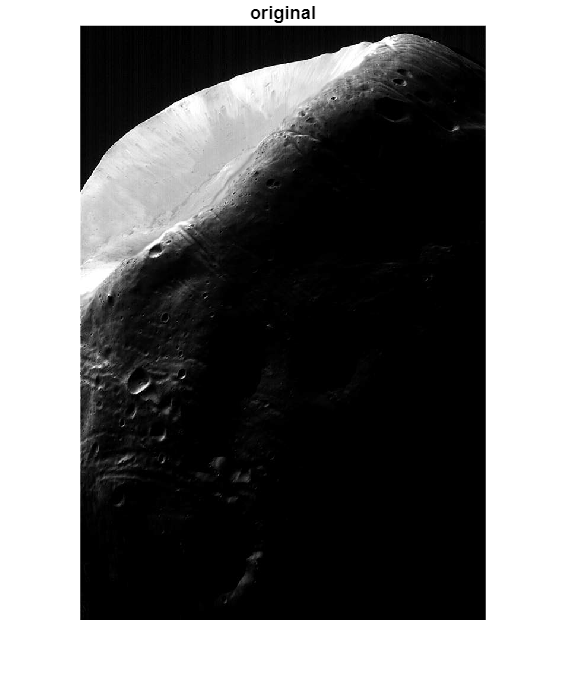

clf('reset')

img = imread('./images/3/Fig3.20(a).jpg');
imshow(img)
title('original')

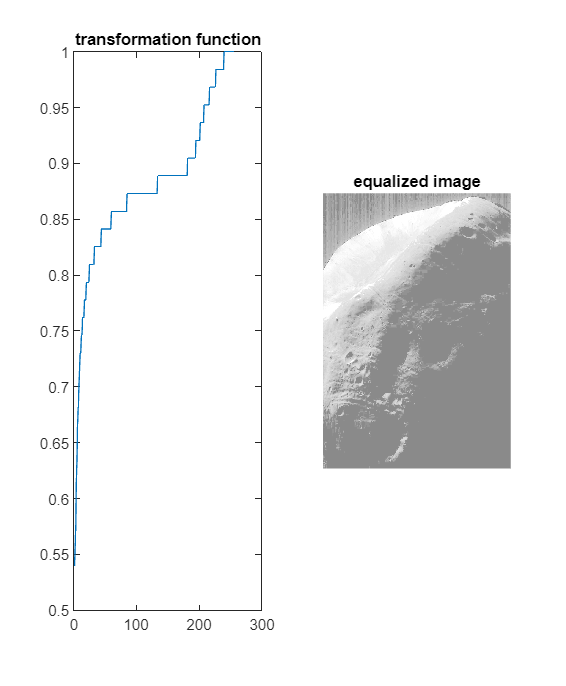


[equaized_img, t] = histeq(img);

subplot(1, 2, 1)
plot(t)
title('transformation function')

subplot(1, 2, 2)
imshow(equaized_img)
title('equalized image')

## Exercise-5-1

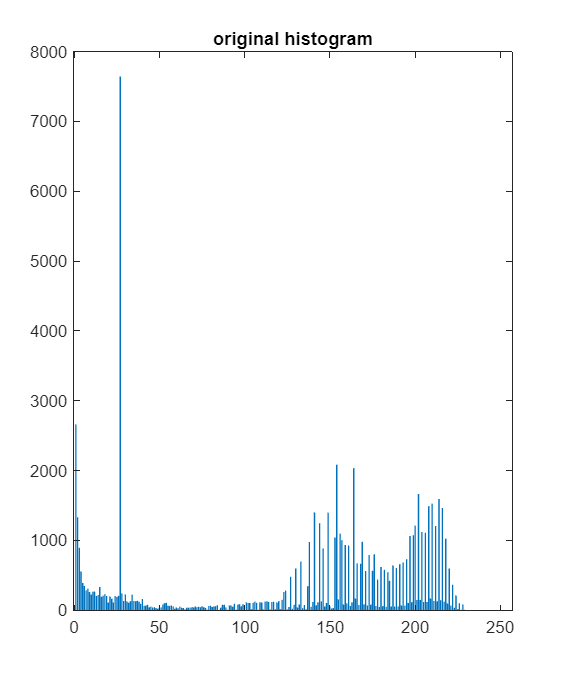

clf('reset')

img = imread('./images/3/Fig3.24.jpg');

hist = gen_hist(img);
bar(hist)
title('original histogram')

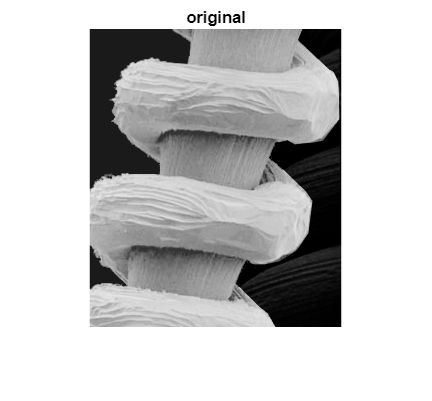


imshow(img)
title('original')

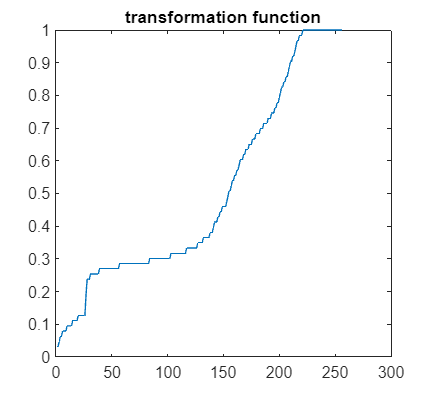


[equaized_img, t] = histeq(img);

plot(t)
title('transformation function')

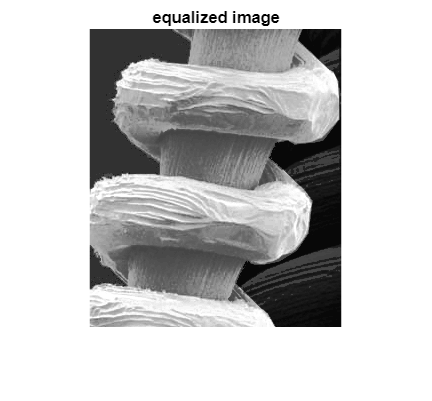


imshow(equaized_img)
title('equalized image')

## Exercise-5-2

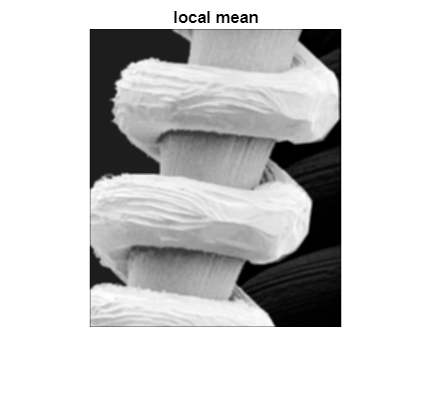

A = double(img);
I1 = nlfilter(img, [3 3], 'mean2');
I2 = nlfilter(img, [3 3], 'std2');

imshow(I1, [])
title('local mean')

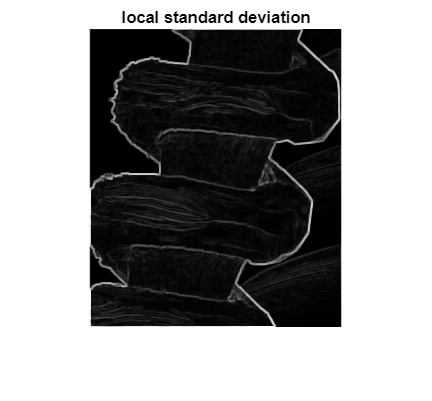


imshow(I2, [])
title('local standard deviation')

### Local enhancement

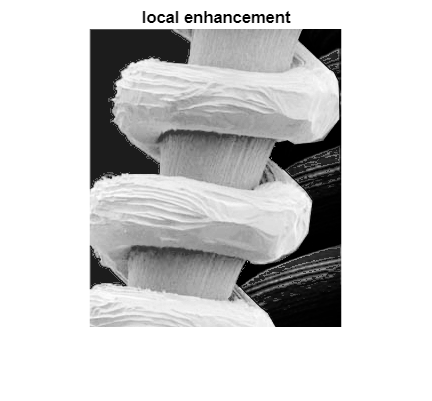

I3 = A;

for x = 1:size(I3, 1)
    for y = 1:size(I3, 2)
        if I1(x, y) <= 40 && I2(x, y) >= 5
            I3(x, y) = I3(x, y) * 3;
        end
    end
end

imshow(I3, [])
title('local enhancement')

function ret = gen_hist(I)
    % Initial histogram vector
    ret = zeros(256, 1);
    [row, col] = size(I);

    for x = 1:row
        for y = 1:col
            ret(I(x, y) + 1) = ret(I(x, y) + 1) + 1;
        end
    end
end